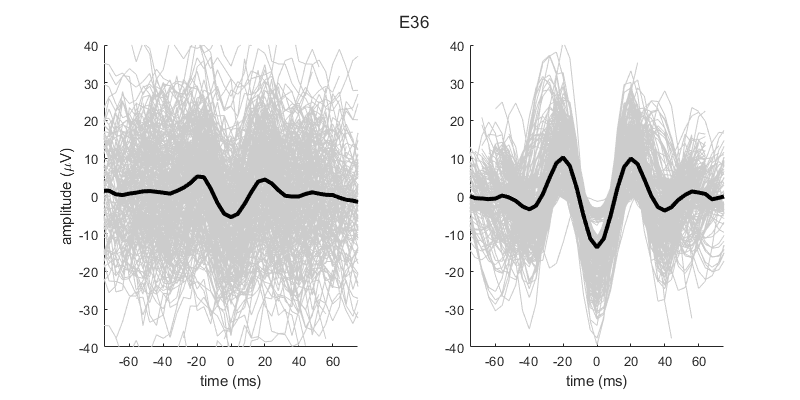

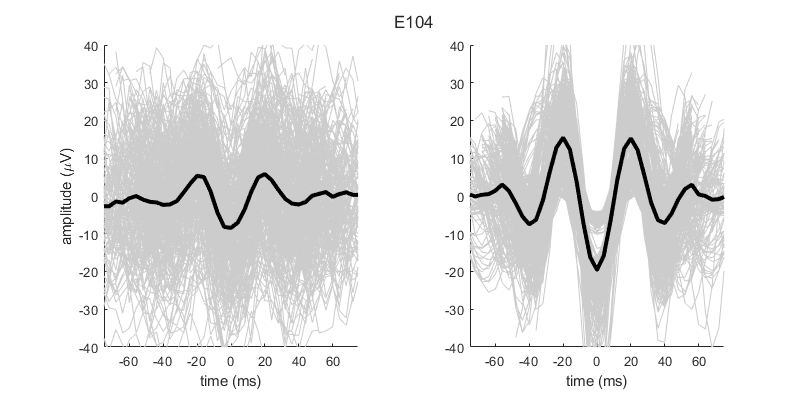

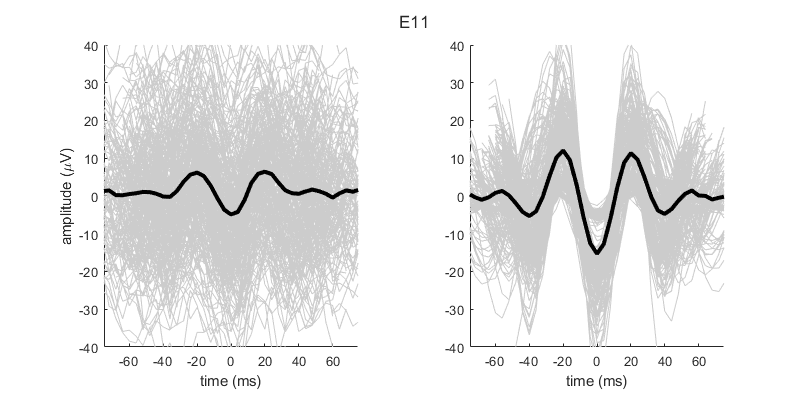

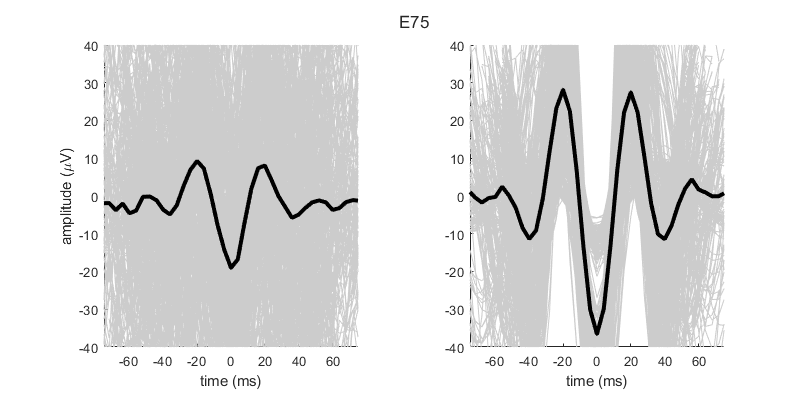

chans  = [36 104 11 75];
half_cyc_n_samp = ceil(2.5 * ceil(1000/P.band.range(1) * C.Fs/1000));
x = [-half_cyc_n_samp:1:0 1:1:half_cyc_n_samp] * 1000/C.Fs;

for ch = chans
    y  = cell2mat({SE_ts(ch).events.y}');
    yf = cell2mat({SE_ts(ch).events.y_filt}');
    figure('Position',[50 200 800 400]); f = tiledlayout(1,2); title(f,['E' int2str(ch)])
    nexttile; hold on; plot(x,y','Color','#ccc'); 
    plot(x,mean(y,1,'omitnan'),'LineWidth',3,'Color','#000'); 
    xlim([-75 75]); ylim([-40 40]); xlabel('time (ms)'); ylabel('amplitude (\muV)')
    nexttile; hold on;  plot(x,yf','Color','#ccc'); 
    plot(x,mean(yf,1,'omitnan'),'LineWidth',3,'Color','#000')
    xlim([-75 75]); ylim([-40 40]); xlabel('time (ms)');
end